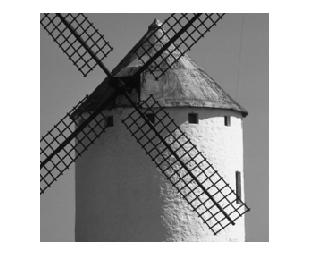

%imwrite(b11, ’b11.tif’, ’Resolution’, 150);
%Kommandot sparar bilden med upplösningen 150 dots (eller pixlar)/tum 
% i tif format
clear;
kvarn = imread('kvarn.tif');
kvarn = im2double(kvarn);
imshow(kvarn);

% 1.1 
b11 = (kvarn >= 0.5)

b11 = 512×512 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

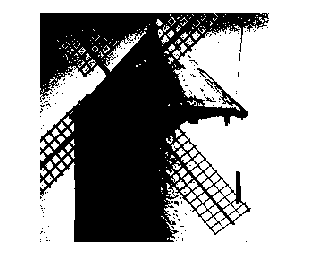

imshow(b11)

imwrite(b11, 'b11.tif', 'Resolution', 150);

% 1.2
load('troskelmatriser.mat')
tr1 = tr1/19

tr1 =     0.4737    0.3684    0.4211    0.5263    0.6316    0.5789
    0.3158    0.0526    0.1053    0.6842    0.9474    0.8947
    0.2632    0.2105    0.1579    0.7368    0.7895    0.8421
    0.5263    0.6316    0.5789    0.4737    0.3684    0.4211
    0.6842    0.9474    0.8947    0.3158    0.0526    0.1053
    0.7368    0.7895    0.8421    0.2632    0.2105    0.1579


tr2 = tr2/33

tr2 =     0.4242    0.3636    0.3939    0.4848    0.5758    0.6364    0.6061    0.5152
    0.1515    0.1212    0.0909    0.3030    0.8485    0.8788    0.9091    0.6970
    0.1818    0.0303    0.0606    0.3333    0.8182    0.9697    0.9394    0.6667
    0.2727    0.2121    0.2424    0.4545    0.7273    0.7879    0.7576    0.5455
    0.5758    0.6364    0.6061    0.5152    0.4242    0.3636    0.3939    0.4848
    0.8485    0.8788    0.9091    0.6970    0.1515    0.1212    0.0909    0.3030
    0.8182    0.9697    0.9394    0.6667    0.1818    0.0303    0.0606    0.3333
    0.7273    0.7879    0.7576    0.5455    0.2727    0.2121    0.2424    0.4545


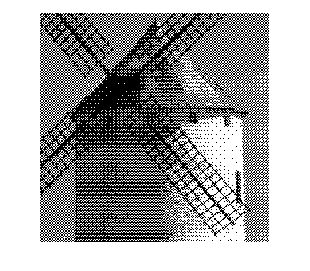

b12_tr1 = troskel(kvarn, tr1);
imshow(b12_tr1)

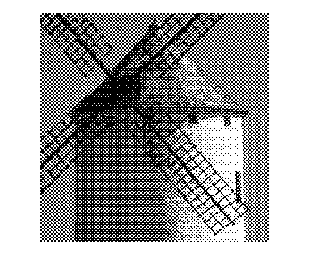

b12_tr2 = troskel(kvarn, tr2);
imshow(b12_tr2)

imwrite(b12_tr1, 'b12_tr1.tif', 'Resolution', 150);
imwrite(b12_tr2, 'b12_tr2.tif', 'Resolution', 150);

% 1.3
tr3 = tr3/33

tr3 =     0.0303    0.9091    0.2424    0.8485    0.0606    0.8788    0.2121    0.8182
    0.5152    0.2727    0.7273    0.4848    0.5455    0.3030    0.6970    0.4545
    0.1515    0.7576    0.0909    0.9697    0.1818    0.7879    0.1212    0.9394
    0.6364    0.3939    0.5758    0.3333    0.6667    0.4242    0.6061    0.3636
    0.0606    0.8788    0.2121    0.8182    0.0303    0.9091    0.2424    0.8485
    0.5455    0.3030    0.6970    0.4545    0.5152    0.2727    0.7273    0.4848
    0.1818    0.7879    0.1212    0.9394    0.1515    0.7576    0.0909    0.9697
    0.6667    0.4242    0.6061    0.3636    0.6364    0.3939    0.5758    0.3333


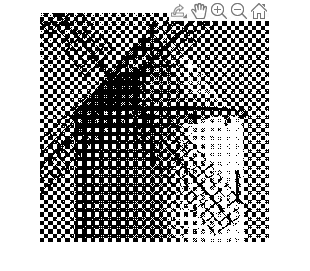

b13 = troskel(kvarn, tr3);
imshow(b13)

imwrite(b13, 'b13.tif', 'Resolution', 150);

% 1.4
linje = [1, 2, 3, 4;
    5, 6, 7, 8;
    9, 10, 11, 12;
    13, 14, 15, 16]/17;
spiral = [10, 9, 8, 7;
        11, 2, 1, 6;
        12, 3, 4, 5;
        13, 14, 15, 16] / 17;

b14_linje = troskel(kvarn, linje)

b14_linje = 512×512 logical array
   1   1   1   1   1   1   1   1   1   1   0   0   1   1   1   1   1   1   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   1   0   0   0   1   1   1   1   1   1
   1   1   1   0   1   1   1   0   1   0   0   0   1   0   0   0   0   0   0   0   1   0   1   0   1   1   1   0   1   1   1   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   1   0   1   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0  

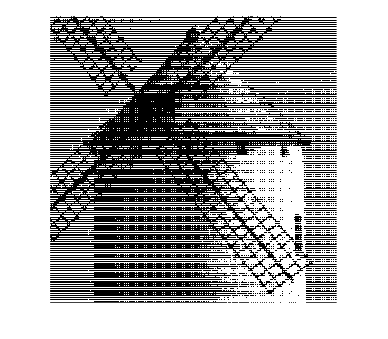

imshow(b14_linje)

imwrite(b14_linje, 'b14_linje.tif', 'Resolution', 150);

b14_spiral = troskel(kvarn, spiral)

b14_spiral = 512×512 logical array
   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0
   0   1   1   1   0   1   1   1   0   1   1   0   0   1   1   1   0   1   1   0   0   1   1   1   0   1   1   1   0   1   1   1   0   1   1   0   0   0   1   0   0   0   1   0   0   1   1   1   0   1
   0   1   1   1   0   1   1   1   0   1   1   0   0   0   0   0   0   0   1   1   0   1   1   1   0   1   1   1   0   1   1   1   0   1   1   1   0   0   0   0   0   0   0   0   0   0   1   0   0   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0 

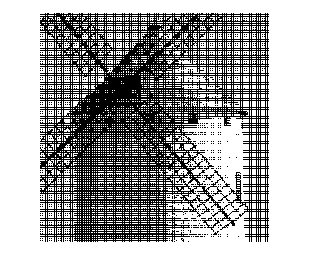

imshow(b14_spiral)

imwrite(b14_spiral, 'b14_spiral.tif', 'Resolution', 150);

% 2.1
b21 = tabellrast(kvarn)

b21 = 512×512 logical array
   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0
   1   1   1   0   1   1   1   0   0   1   1   0   0   1   1   0   0   1   1   0   1   1   1   0   1   1   1   0   1   1   1   0   1   1   1   0   0   1   0   0   0   1   0   0   0   1   1   0   1   1
   1   1   1   0   1   1   1   0   0   1   1   0   0   0   1   0   0   0   1   0   1   1   1   0   1   1   1   0   1   1   1   0   1   1   1   0   0   0   0   0   0   0   0   0   0   1   1   0   1   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0

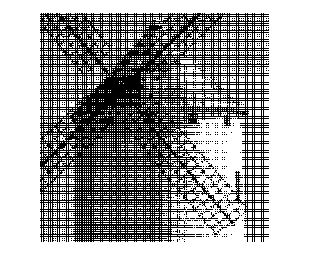

imshow(b21)

imwrite(b21, 'b21.tif', 'Resolution', 150);

% 2.2
b22 = tabellrast2(kvarn)

b22 = 512×512 logical array
   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0   0   0   1   0   1   0   1   0
   0   1   0   1   0   1   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1
   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0   0   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   0   0   0   0   0   0   1   0   1   0   1   0
   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0

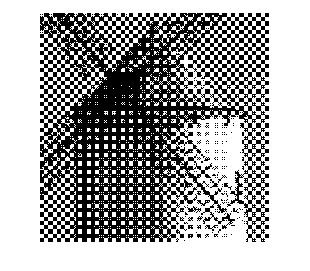

imshow(b22)

imwrite(b22, 'b22.tif', 'Resolution', 150);